# Problem Set 3: STA and STC

CPNS 35600, Mia Paletta, Spring 2021

*Collaborator: Ariana Tortolani*

## P1: Bussgang's Theorem

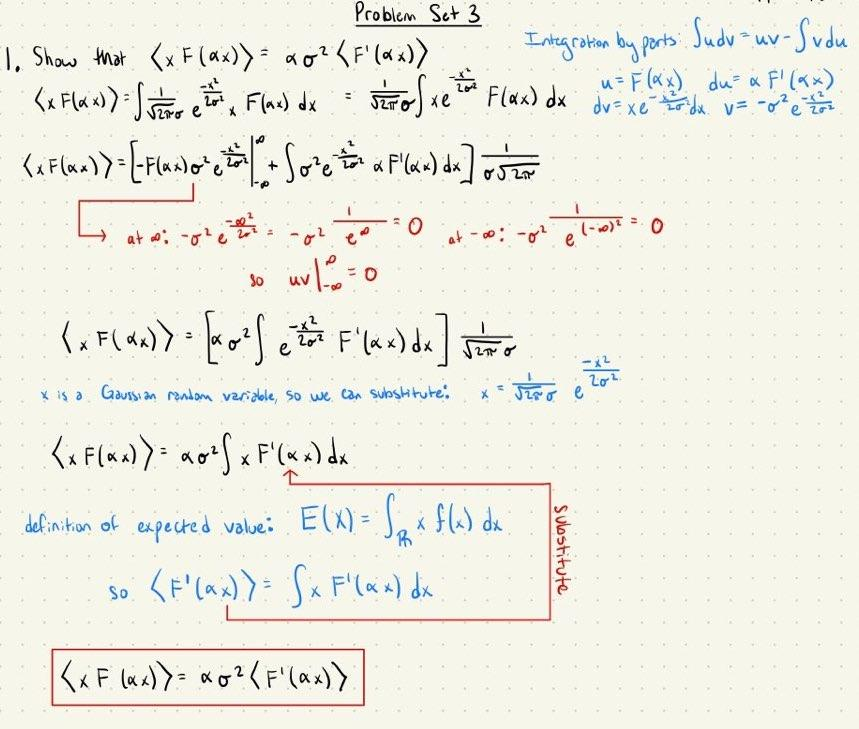

## P2: Fly data STA

- Data collected for 20min at 500Hz: 500spikes/s * 60s/min * 20min = 600,000 data pts

- rho - binned spikes (2ms bins)

- stim - stimulus values at a bin

- plan: look at 100ms before each spike, or 50 time points of the stim

% load the data

load("fly_data.mat") % produces rho and stim

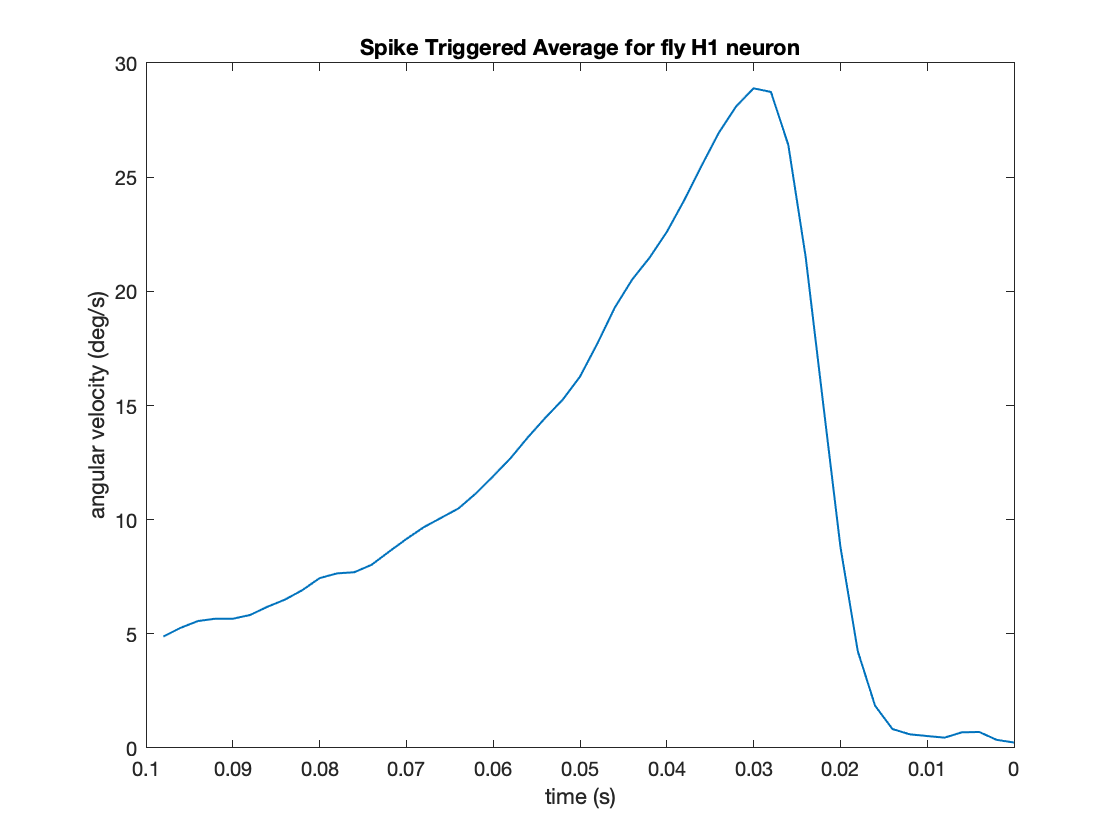

% find spike inds

spike_inds = find(rho(1:end/2));

% create array of pre-spike stimulus - 50 samples

tau = 50; % num of samples to calculate STA over

spike_inds_tau = spike_inds(spike_inds > tau); % ensure enough samples exist for STA

stim_array = zeros(tau, length(spike_inds_tau));

for i = 1:length(spike_inds_tau)
    stim_array(:,i) = stim(spike_inds_tau(i) - (tau-1):spike_inds_tau(i));
end

% compute STA
STA = mean(stim_array,2);

% plot STA
STA_times = fliplr([0:tau-1] * 0.002);

figure
plot(STA_times, STA, 'LineWidth', 1)
xlabel('time (s)')
set(gca, 'xdir','reverse')
ylabel('angular velocity (deg/s)')
title('Spike Triggered Average for fly H1 neuron')

## P3: Estimate nonlinearity of H1 neuron

- Compute distribution of overlap between STA and stimulus at a random sample (or all) stimulus frames in the first half of the data - convolve STA with the stimulus: $P\left(L\right)$

- Condition distribution on presence of a spike: $P\left(L\left|\textrm{spike}\right.\right)$

- Estimate nonlinearity, $P\left(\textrm{spike}\left|L\right.\right)$, using the ratio: $P\left(\textrm{spike}\left|L\right.\right)\propto \frac{P\left(L\left|\textrm{spike}\right.\right)}{P\left(L\right)}$

- Plot the three quantities

% convolve the STA with the stimulus to find P(L)

L = zeros(1, length(stim(tau:end/2)));

for i = tau:length(stim(1:end/2))
    L(i - tau + 1) = sum(STA .* stim(i-tau+1:i));
end

% convolve STA w stimulus conditioned on presence of spike: P(L|spike)

% we can use stim_array from question 2 to make this easier

L_spike = zeros(1, size(stim_array, 2));

for i = 1:size(stim_array, 2)
    L_spike(i) = sum(STA .* stim_array(:,i));
end


% find min and max of both L and L|spike to create bin edges

min_bin = min([min(L), min(L_spike)]);
max_bin = max([max(L), max(L_spike)]);

bin_edges = linspace(min_bin, max_bin, 51);

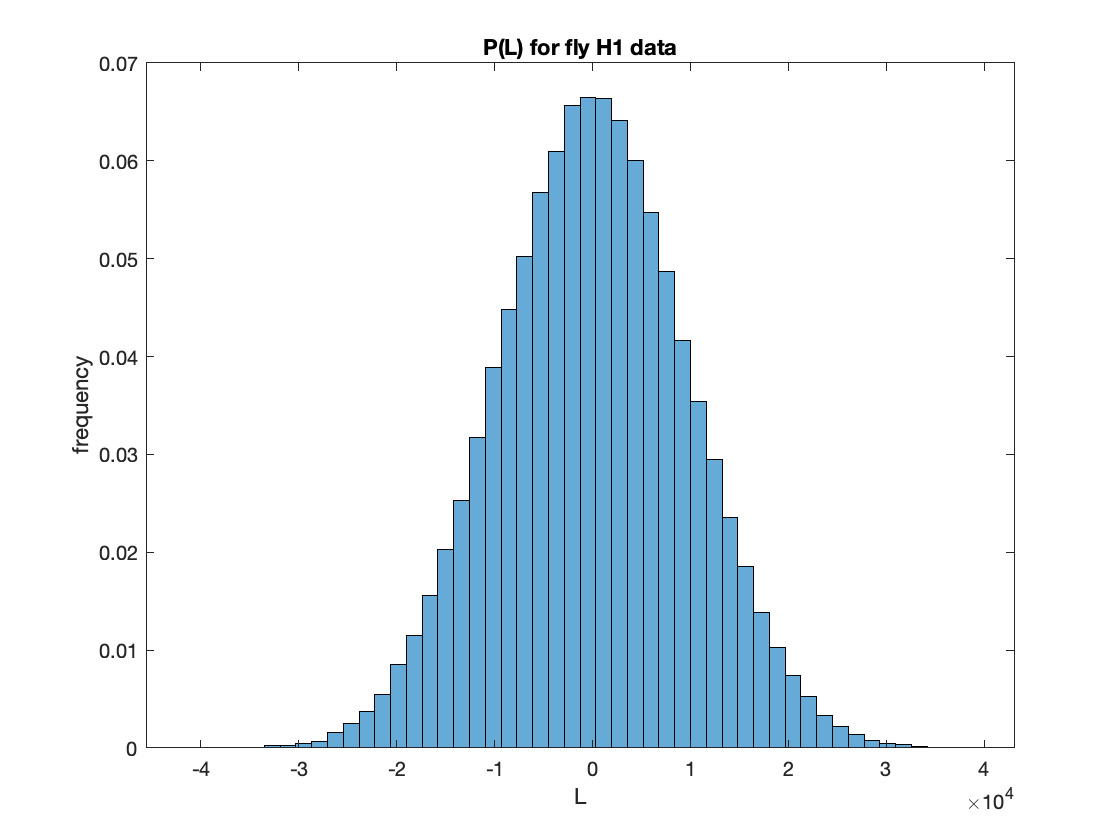

% find P(L) by binning L

[PL_counts PL_edges] = histcounts(L, bin_edges);

PL = PL_counts ./ sum(PL_counts);

% plot P(L)
figure
histogram('BinCounts', PL, "BinEdges", bin_edges)
xlabel('L')
ylabel('frequency')
title('P(L) for fly H1 data')

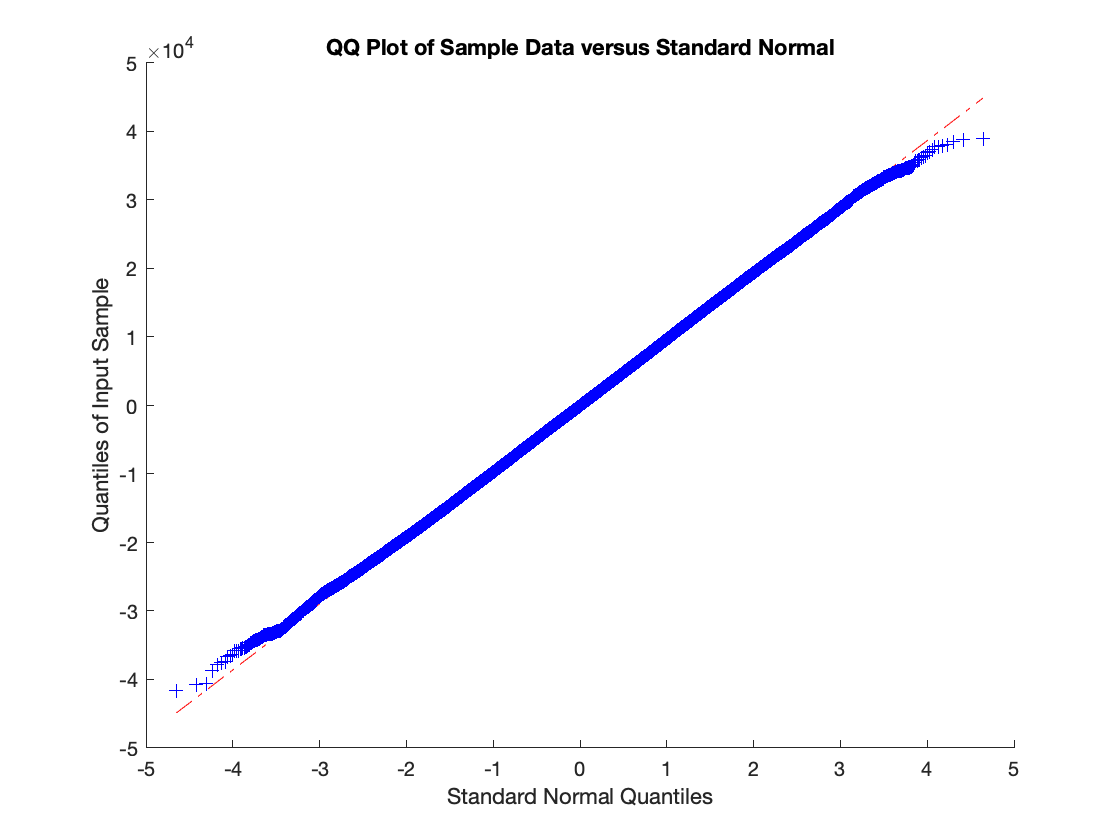


figure
qqplot(L) % visually check to see if normally distributed

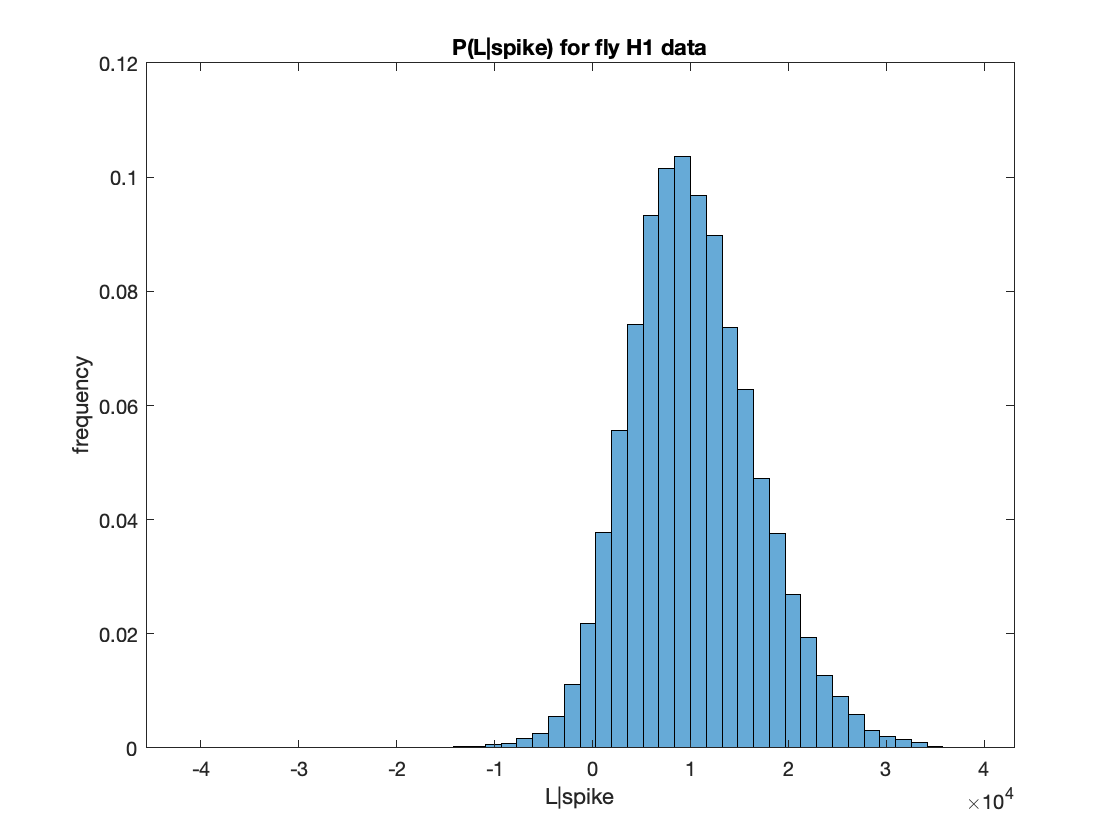

% find P(L|spike) by binning L_spike

[PL_spike_counts PL_spike_edges] = histcounts(L_spike, bin_edges);

PL_spike = PL_spike_counts ./ sum(PL_spike_counts);

% plot P(L|spike)
figure
histogram('BinCounts', PL_spike, "BinEdges", bin_edges)
xlabel('L|spike')
ylabel('frequency')
title('P(L|spike) for fly H1 data')

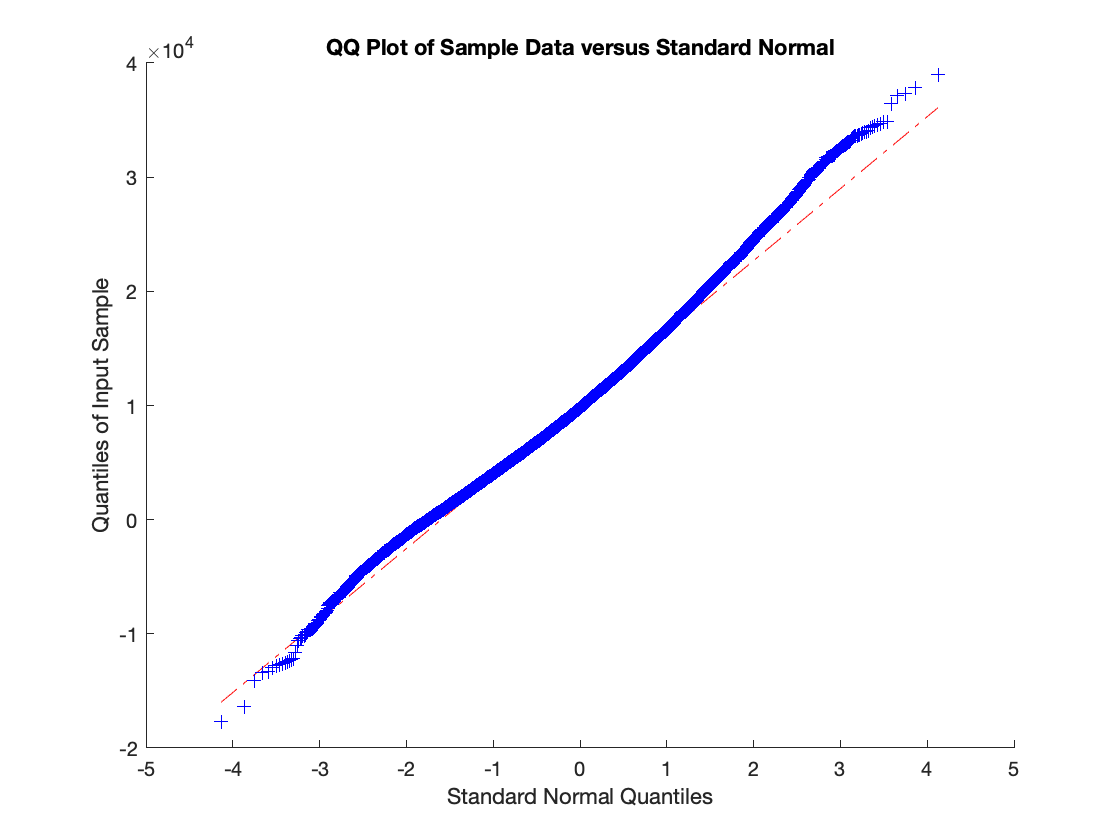


figure
qqplot(L_spike) % test for normal distribution

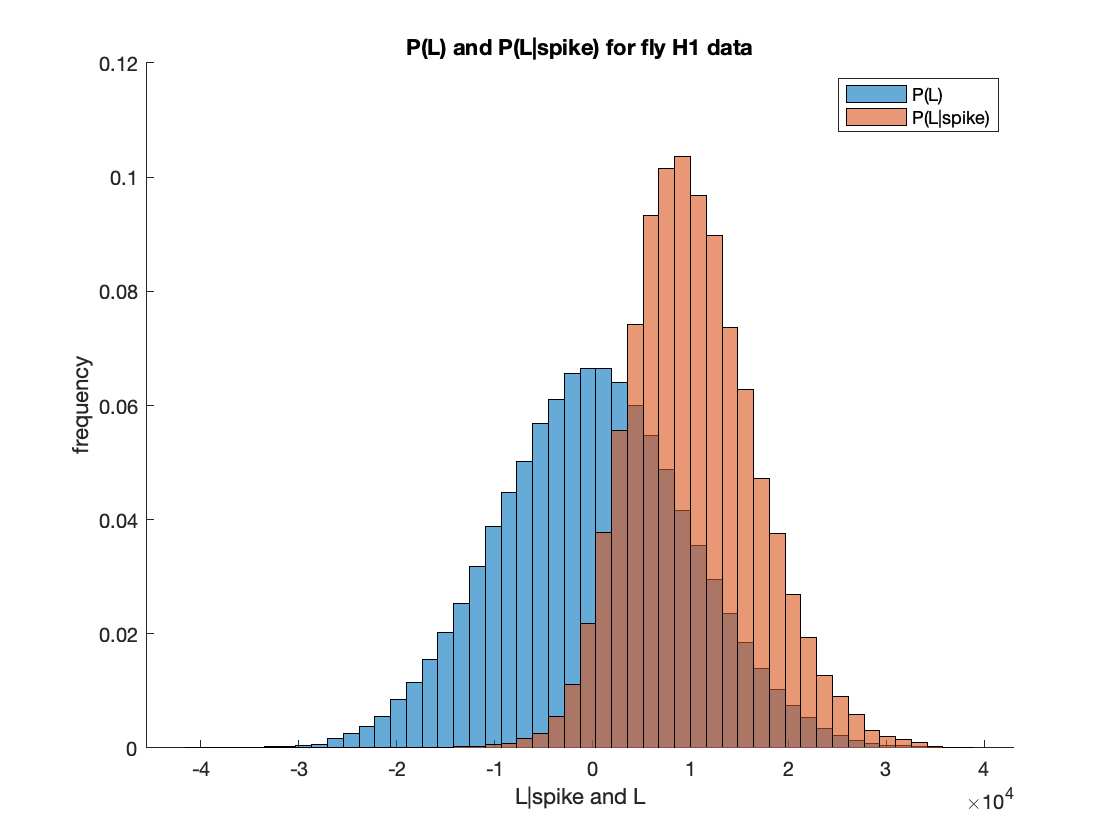


% plot the overlap of the two distributions
figure
hold on
histogram('BinCounts', PL, "BinEdges", bin_edges)
histogram('BinCounts', PL_spike, "BinEdges", bin_edges)
xlabel('L|spike and L')
ylabel('frequency')
title('P(L) and P(L|spike) for fly H1 data')
legend('P(L)', 'P(L|spike)')

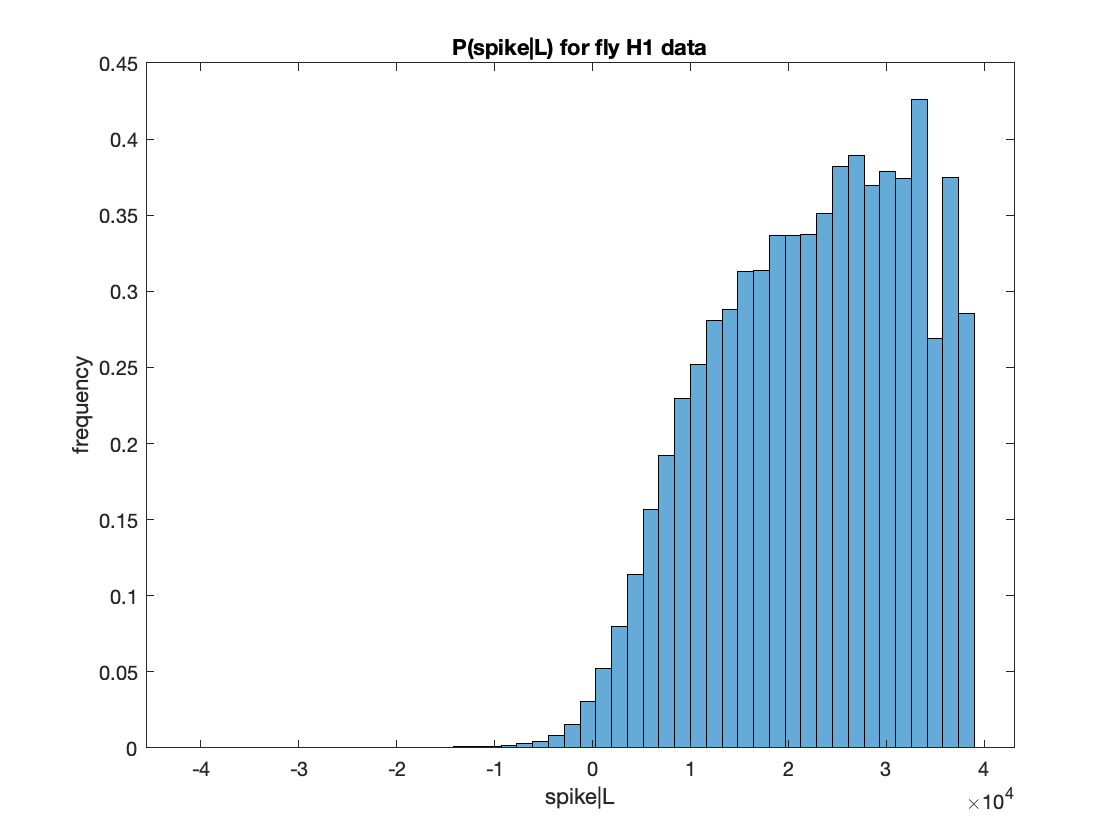

% estimate P(spike|L) by taking the ratio P(L|spike) / P(L)
Pspike = sum(rho(1:end/2)) / length(rho(1:end/2));

Pspike_L = (PL_spike ./ PL) .* Pspike;

% plot P(spike|L)
figure
histogram('BinCounts', Pspike_L, "BinEdges", bin_edges)
xlabel('spike|L')
ylabel('frequency')
title('P(spike|L) for fly H1 data')

## P4: Generating spikes from LNP model

% find the estimated firing rate, r_est

% find the convolution L(t) of the STA with the 2nd half of the stimulus
L2 = zeros(1, length(stim)/2);

for i = tau+length(stim)/2:length(stim) - 1
    L2(i-length(stim)/2+1) = sum(STA .* stim(i-tau+1:i));
end

% find which bin of P(spike|L) the L2 values fall in to get P(spike|L) val
Pspike_L2 = zeros(1, length(L2));

for i = 1:length(L2)
    mask = bin_edges <= L2(i);
    bin = max(find(mask));
    Pspike_L2(i) = Pspike_L(bin);
end

% find r_est by dividing the probabilities by delta t
dt = 0.002;
r_est = Pspike_L2 ./ dt; % 2ms dt, gives rate in spikes/s

% generate Poisson model: spike if r_est * dt > x_rand
model_spikes = zeros(1,length(r_est));

for i = 1:length(r_est)
    if (r_est(i) * dt) > rand
        model_spikes(i) = 1;
    end
end

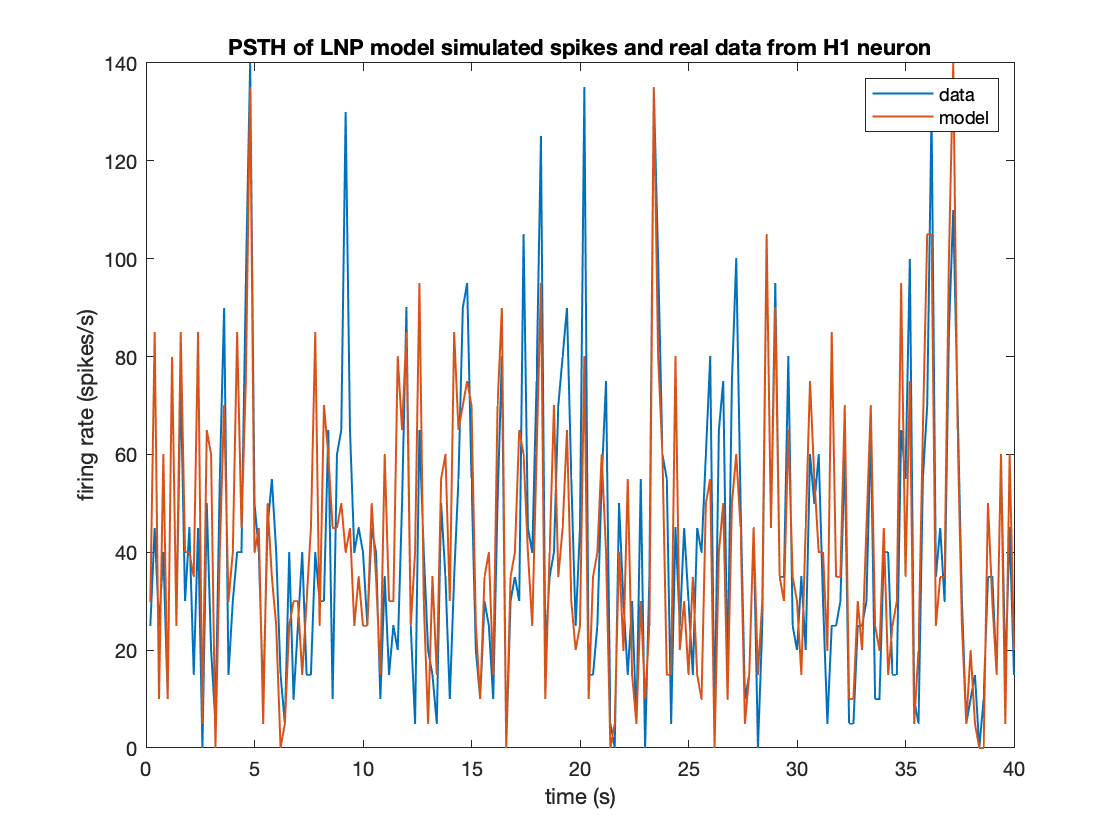

% make PSTH for real and model data to compare

% put the data in 20ms time bins and calculate the instantaneous rate
data_reshaped = reshape(rho(end/2+1:end), 100, []); % 200ms window
PSTH_data = sum(data_reshaped) ./ 0.2;

% repeat for the model data
model_reshaped = reshape(model_spikes, 100, []); % 200ms window
PSTH_model = sum(model_reshaped) ./ 0.2;

% plot the real and model data
PSTH_times = [1:3000] * 0.2;
figure
plot(PSTH_times(1:200), PSTH_data(1:200), PSTH_times(1:200), PSTH_model(1:200), 'LineWidth', 1)
xlabel('time (s)')
ylabel('firing rate (spikes/s)')
title('PSTH of LNP model simulated spikes and real data from H1 neuron')
legend('data', 'model')

**This model was produced with a 200ms window size.**

## P5: V1 STA and STC

% load the data

cell1 = load("533l006.p05_stc.mat");
cell2 = load("543l021.p07_stc.mat");

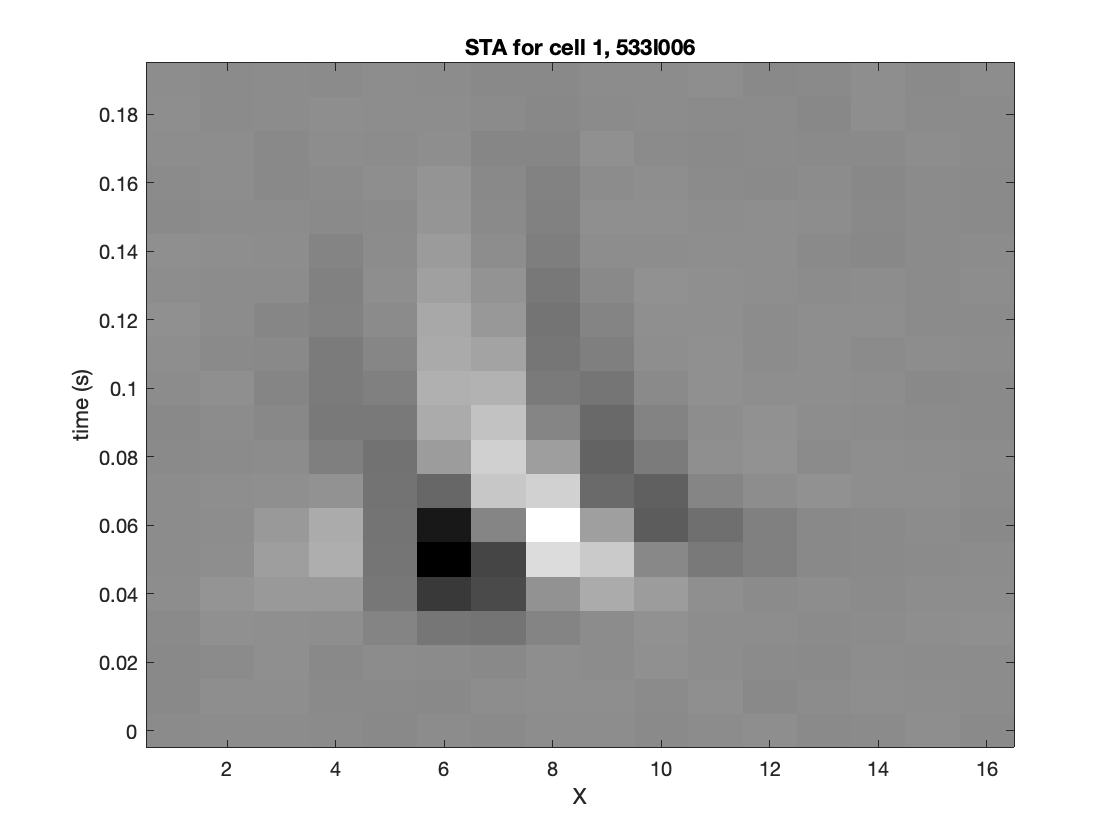

% STA for cell 1

% find spikes and take 20 stim frames before each spike
c1_spk_locs = find(cell1.spikes_per_frm);

c1_spk_locs = c1_spk_locs(c1_spk_locs > 20);

c1_spk_frames = zeros(20, size(cell1.stim, 2), length(c1_spk_locs));

% create a 3d array of the stimulus frames that precedes spikes
for i = 1:length(c1_spk_locs) % loop over indices of spikes
    c1_spk_frames(:,:,i) = cell1.stim(c1_spk_locs(i)-19:c1_spk_locs(i), :);
end

c1_STA = mean(c1_spk_frames, 3);

% plot the STA
figure
colormap gray
imagesc(c1_STA)
title('STA for cell 1, 533l006')
xlabel('X')
ylabel('time (s)')
yticklabels(0.18:-0.02:0)

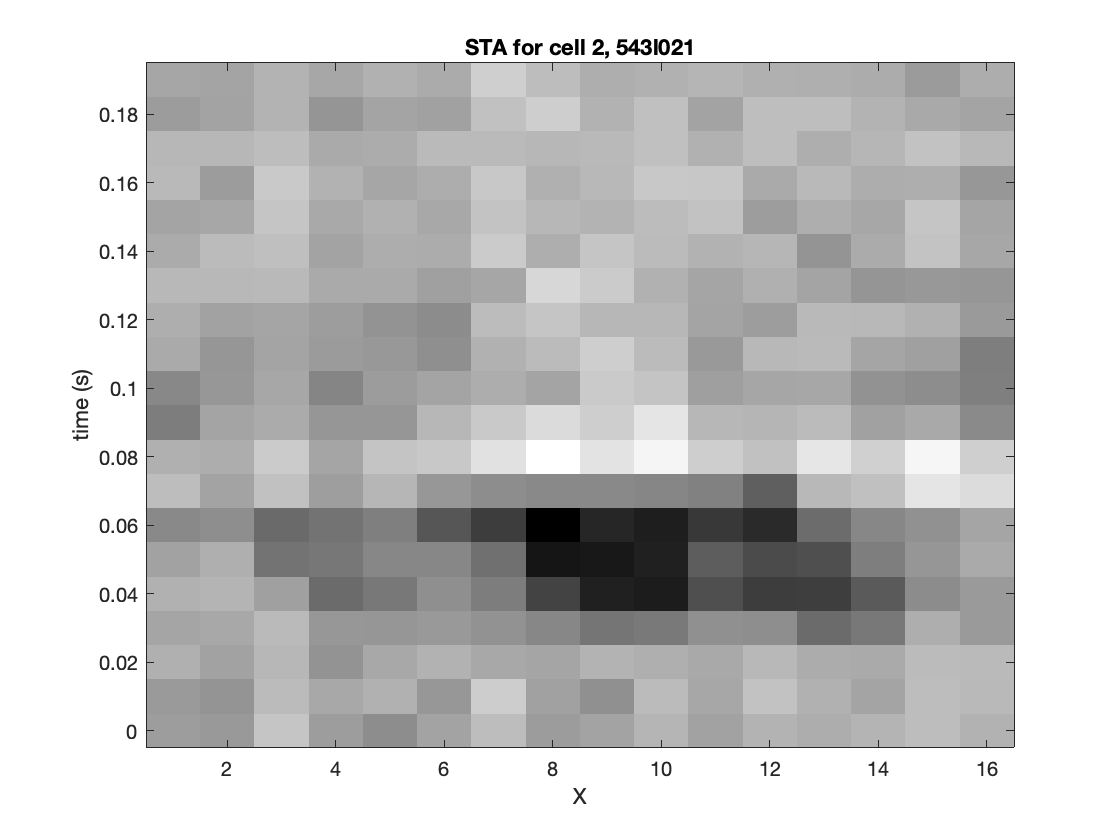

% STA for cell 2

% find spikes and take 20 stim frames before each spike
c2_spk_locs = find(cell2.spikes_per_frm);

c2_spk_locs = c2_spk_locs(c2_spk_locs > 20);

c2_spk_frames = zeros(20, size(cell2.stim, 2), length(c2_spk_locs));

% create a 3d array of the stimulus frames that precedes spikes
for i = 1:length(c2_spk_locs) % loop over indices of spikes
    c2_spk_frames(:,:,i) = cell2.stim(c2_spk_locs(i)-19:c2_spk_locs(i), :);
end

c2_STA = mean(c2_spk_frames, 3);

% plot the STA
figure
colormap gray
imagesc(c2_STA)
title('STA for cell 2, 543l021')
xlabel('X')
ylabel('time (s)')
yticklabels(0.18:-0.02:0)

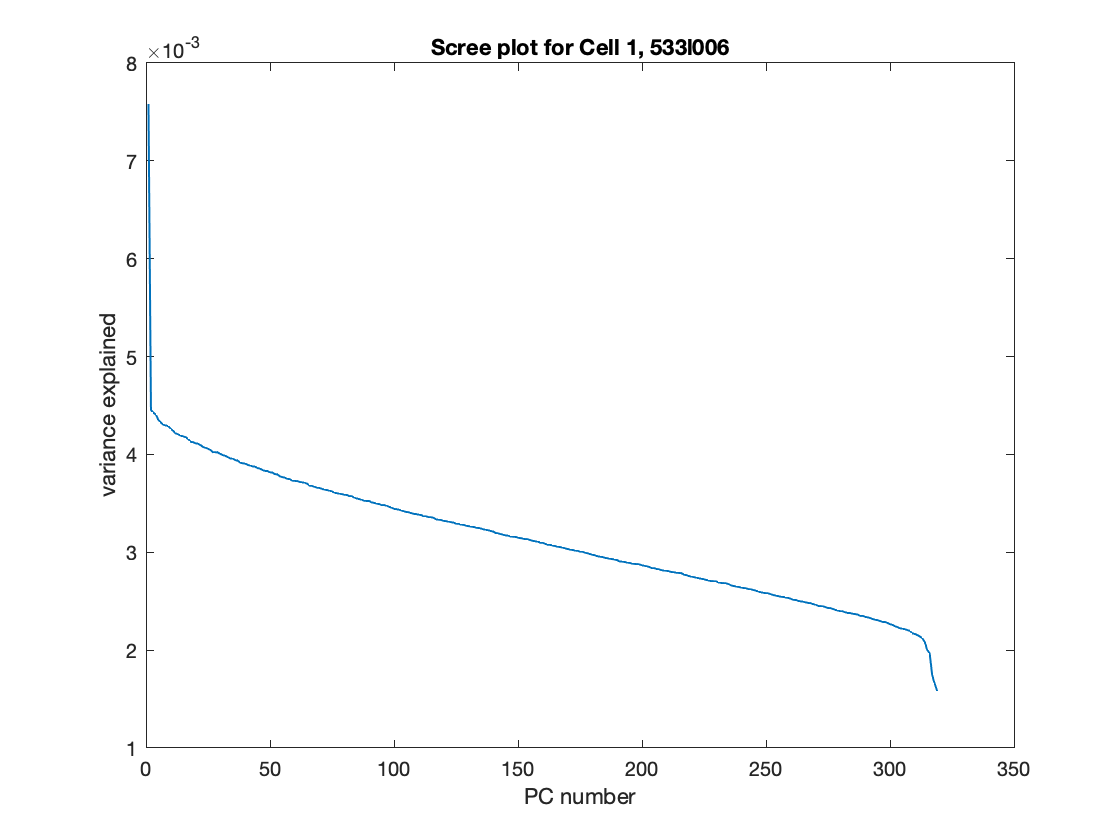

% STC for cell 1

% reshape the STA to be 1D
c1_STA_vec = reshape(c1_STA, 1, []);

c1_spk_frames_STC = zeros(size(c1_spk_frames, 3), length(c1_STA_vec));

for i = 1:size(c1_spk_frames, 3)
    c1_spk_frames_STC(i,:) = reshape(c1_spk_frames(:,:,i), 1, []);
end

% repeat STA by num frames to make subtraction simple
c1_STA_repeated = repmat(c1_STA_vec, size(c1_spk_frames_STC, 1), 1);

% subtract the STA from the stimulus
c1_stim_minus_STA = c1_spk_frames_STC - c1_STA_repeated;

% make covariance matrix
c1_covmat = cov(c1_stim_minus_STA);

% run PCA on the covariance matrix to find significant eigenvectors
[c1_coeff, c1_score, c1_latents] = pca(c1_covmat);

c1_latents_norm = c1_latents ./ sum(c1_latents);

% scree plot
figure
plot(c1_latents_norm, 'LineWidth', 1)
title('Scree plot for Cell 1, 533l006')
xlabel('PC number')
ylabel('variance explained')

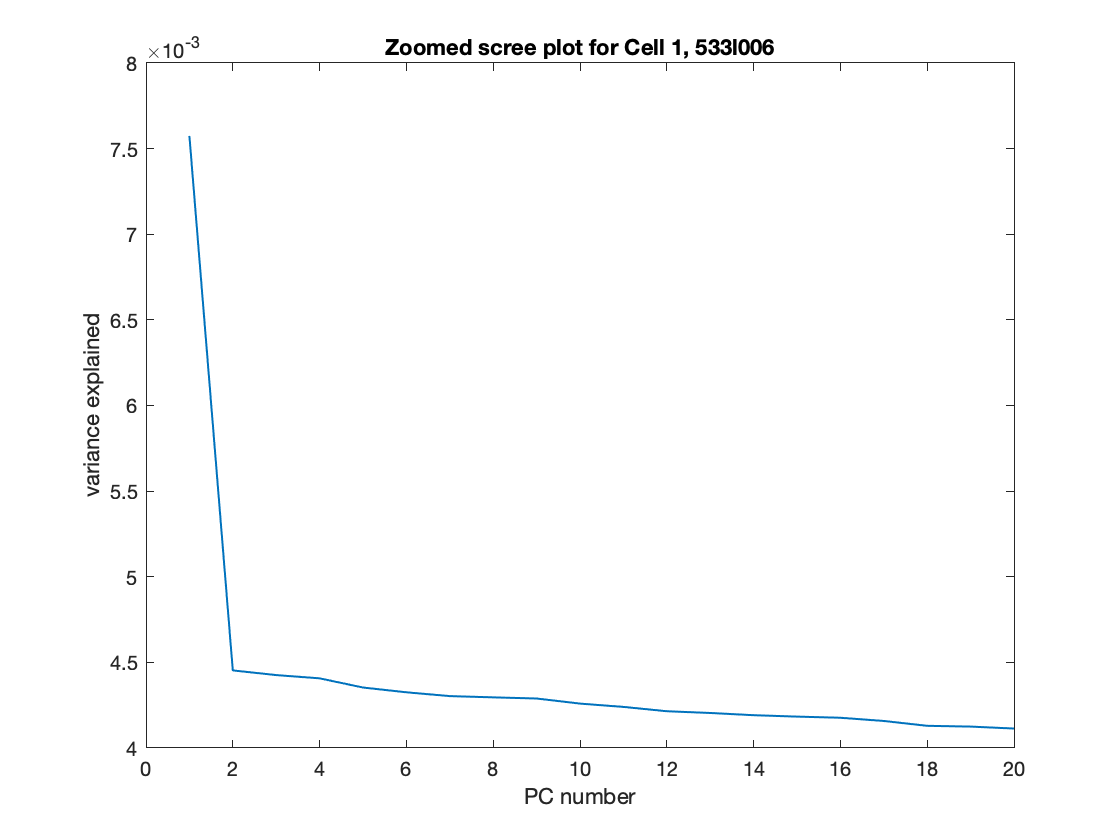


% zoom in on the plot to find out which eigenvectors are most significant
figure
plot(c1_latents_norm(1:20), 'LineWidth', 1)
title('Zoomed scree plot for Cell 1, 533l006')
xlabel('PC number')
ylabel('variance explained')

**From this plot, we see a sharp elbow at 2 eigenvectors. We can assume that only the first two principal components will be significant for this cell.**

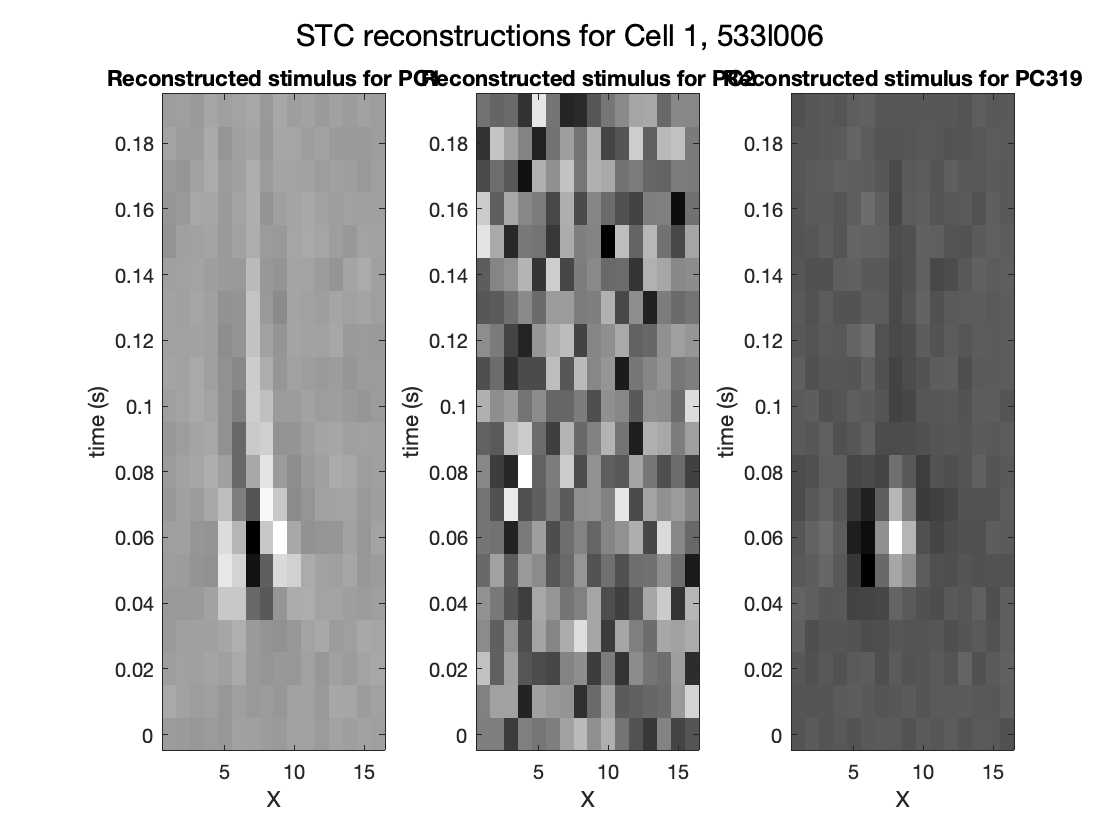

c1_PCs = [1 2 319];
figure

for i = 1:length(c1_PCs)

    c1_reconstruction = c1_score(:,c1_PCs(i)) * c1_coeff(:,c1_PCs(i))'; % reconstruction of stimulus for cell 1, PCi
    
    % take flattened STA and repeat it so it is same dims as reconstruction
    c1_STA_recon_mat = repmat(c1_STA_vec, size(c1_reconstruction, 1), 1);
    
    % add repeated STA to the reconstructions
    c1_recon_plus_STA = c1_reconstruction + c1_STA_recon_mat;

    % reshape recon+STA to get frames back - columns are frames - then average
    c1_frames = zeros(20, 16, size(c1_recon_plus_STA, 1));

    for j = 1:size(c1_recon_plus_STA, 2)
        c1_frames(:,:,j) = reshape(c1_recon_plus_STA(:,j), 20, []);
    end
    
    c1_avg_stim = mean(c1_frames, 3);
    
    % plot the average frames
    subplot(1, 3, i)
    colormap gray
    imagesc(c1_avg_stim)
    title(sprintf('Reconstructed stimulus for PC%d', c1_PCs(i)))
    xlabel('X')
    ylabel('time (s)')
    yticklabels(0.18:-0.02:0)

end

sgtitle('STC reconstructions for Cell 1, 533l006')

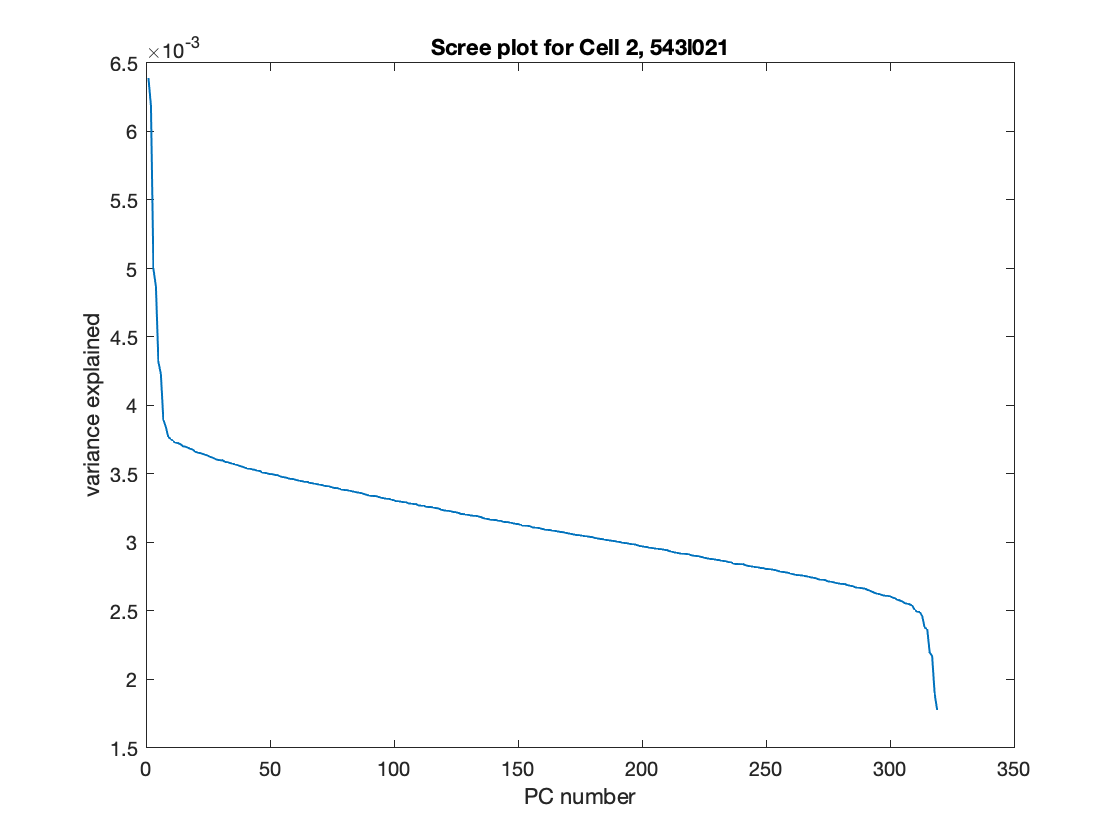

% STC for cell 2

% reshape the STA to be 1D
c2_STA_vec = reshape(c2_STA, 1, []);

c2_spk_frames_STC = zeros(size(c2_spk_frames, 3), length(c2_STA_vec));

for i = 1:size(c2_spk_frames, 3)
    c2_spk_frames_STC(i,:) = reshape(c2_spk_frames(:,:,i), 1, []);
end

% repeat STA by num frames to make subtraction simple
c2_STA_repeated = repmat(c2_STA_vec, size(c2_spk_frames_STC, 1), 1);

% subtract the STA from the stimulus
c2_stim_minus_STA = c2_spk_frames_STC - c2_STA_repeated;

% make covariance matrix
c2_covmat = cov(c2_stim_minus_STA);

% run PCA on the covariance matrix to find significant eigenvectors
[c2_coeff, c2_score, c2_latents] = pca(c2_covmat);

c2_latents_norm = c2_latents ./ sum(c2_latents);

% scree plot
figure
plot(c2_latents_norm, 'LineWidth', 1)
title('Scree plot for Cell 2, 543l021')
xlabel('PC number')
ylabel('variance explained')

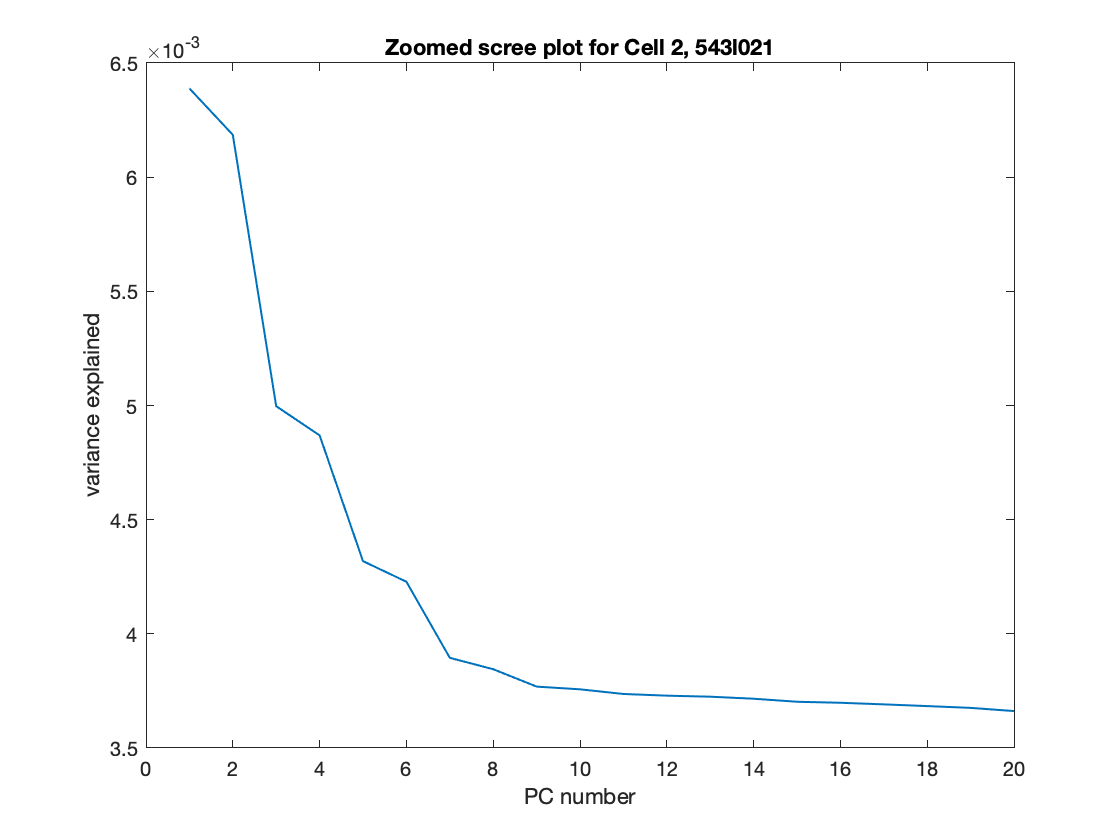


% zoom in on the plot to find out which eigenvectors are most significant
figure
plot(c2_latents_norm(1:20), 'LineWidth', 1)
title('Zoomed scree plot for Cell 2, 543l021')
xlabel('PC number')
ylabel('variance explained')

**From this scree plot, we can see that the variance explained falls off after about the 7th PC. So, we will assume the first 7 PCs are significant for cell 2.**

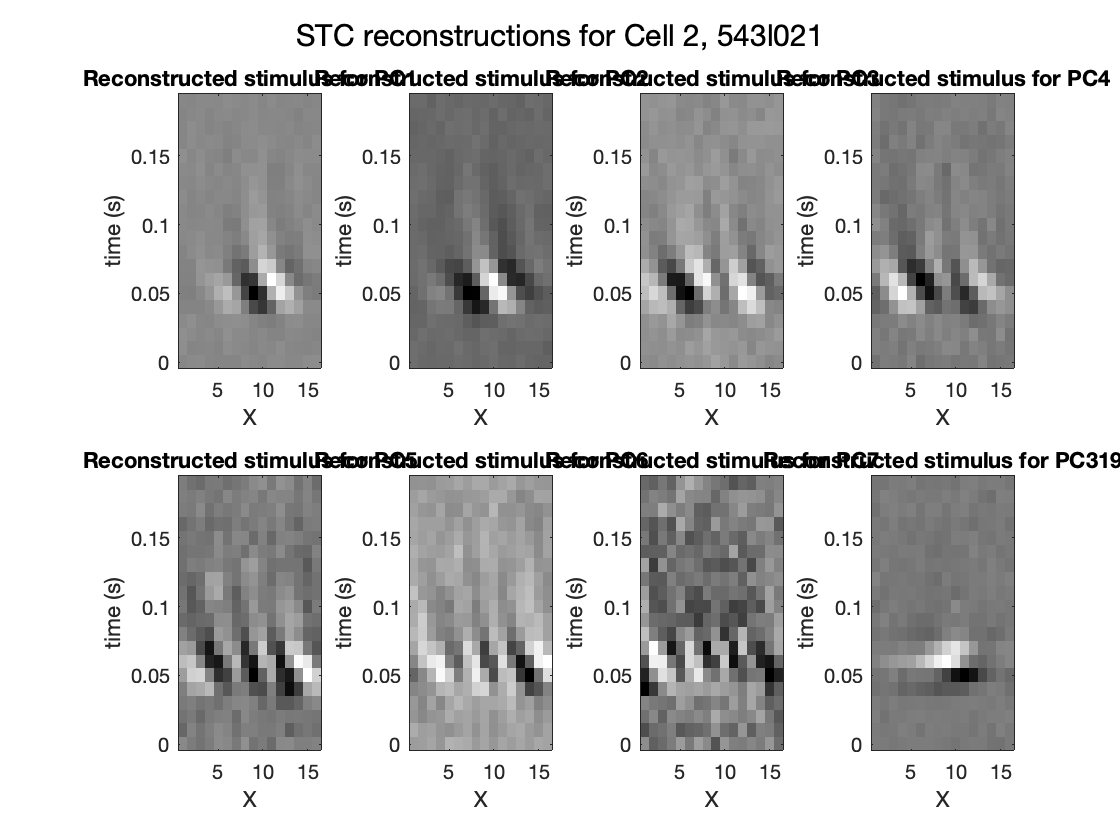

c2_PCs = [1:7 319];

figure

for i = 1:8
    c2_reconstruction = c2_score(:,c2_PCs(i)) * c1_coeff(:,c2_PCs(i))'; % reconstruction of stimulus for cell 2, PCi

    % take flattened STA and repeat it so it is same dims as reconstruction
    c2_STA_recon_mat = repmat(c2_STA_vec, size(c2_reconstruction, 1), 1);
    
    % add repeated STA to the reconstructions
    c2_recon_plus_STA = c2_reconstruction + c2_STA_recon_mat;

    % reshape recon+STA to get frames back - columns are frames - then average
    c2_frames = zeros(20, 16, size(c2_recon_plus_STA, 1));
    
    for j = 1:size(c2_recon_plus_STA, 2)
        c2_frames(:,:,j) = reshape(c2_recon_plus_STA(:,j), 20, []);
    end
    
    c2_avg_stim = mean(c2_frames, 3);
    
    % plot the average frames
    subplot(2, 4, i)
    colormap gray
    imagesc(c2_avg_stim)
    title(sprintf('Reconstructed stimulus for PC%d', c2_PCs(i)))
    xlabel('X')
    ylabel('time (s)')
    yticklabels(0.15:-0.05:0)
end

sgtitle('STC reconstructions for Cell 2, 543l021')

**STC allows you to look at potentially different stimuli that might all be effective on the same cell. In V1, you can encounter both simple and complex cells. Simple cells will show a fairly clearly STA with a specific stimulus that is effective on that cell, but complex cells show much less clarity in the STA because multiple possible effective stimuli are all being averaged. STCs allow us to find the different stimuli for complex cells that the cell will respond best to.**